# **Data Import and Processing**

In this example, we import historical price data for a set of commodities. We then organize and process the data into a suitable form for subsequent analysis.

*Copyright 2022 The MathWorks, Inc.*

## **Import the commodity price data.**

The data is sourced from The World Bank's monthly commodity price data set.

**Reference**

- The World Bank: "Pink Sheet" Data - Monthly prices ([https://www.worldbank.org/en/research/commodity-markets](https://www.worldbank.org/en/research/commodity-markets))

- Terms of use: [https://www.worldbank.org/en/about/legal/terms-of-use-for-datasets](https://www.worldbank.org/en/about/legal/terms-of-use-for-datasets)

The data comprises monthly commodity prices for a diverse collection of commodities.

To run this script, download the data from the source above and save it to a file named `CMO-Historical-Data-Monthly.xlsx`.

Define the options for importing the commodity prices.

filename = "CMO-Historical-Data-Monthly.xlsx";
opts = detectImportOptions(filename, ...
    "Sheet", "Monthly Prices", ...
    "VariableNamingRule", "preserve", ...
    "TextType", "string");

Rename the first variable to `Date`.

opts.VariableNames = replace(opts.VariableNames, "Var1", "Date");

Ensure that all variables apart from the first are numeric.

numVars = length(opts.VariableTypes);
opts.VariableTypes = ["string", repmat("double", 1, numVars - 1)];

Ensure that the variable units are imported in addition to the data.

opts.VariableUnitsRange = "A6";

Import the data.

Prices = readtable(filename, opts);

## Process the raw commodity price data.

First, convert the dates to `datetime` values, then convert the table to a timetable.

Prices.Date = datetime(Prices.Date, ...
    "InputFormat", "yyyy'M'MM", ...
    "Format", "MMM yyyy");
Prices = table2timetable(Prices);

Associate high-level classes with each commodity. We will use these high-level classes to extract the soft commodities from the larger data set.

commodityClasses = categorical([repmat("Energy", 1, 10), ...
    repmat("Beverages", 1, 7), ...
    repmat("Oils and Meals", 1, 11), ...
    repmat("Grains", 1, 9), ...
    repmat("Other Food", 1, 10), ...
    repmat("Raw Materials", 1, 9), ...
    repmat("Fertilizers", 1, 5), ...
    repmat("Metals and Minerals", 1, 7), ...
    repmat("Precious Metals", 1, 3)] );

Prices = addprop(Prices, "CommodityClass", "variable");
Prices.Properties.CustomProperties.CommodityClass = commodityClasses;

Similarly, associate a hard/soft label with each commodity, using the commodity classes defined above.

commodityTypes = categorical(repmat("Soft", 1, width(Prices)));
hardClasses = categorical(["Energy", "Fertilizers", "Metals and Minerals", "Precious Metals"]);
hardIdx = ismember(commodityClasses, hardClasses);
commodityTypes(hardIdx) = "Hard";

Prices = addprop( Prices, "CommodityType", "variable" );
Prices.Properties.CustomProperties.CommodityType = commodityTypes;

## Create a portfolio of soft commodities.

Extract the soft commodities which have non-missing data for the entire period.

soft = Prices.Properties.CustomProperties.CommodityType == "Soft";
intact = all(~ismissing(Prices));
Prices = Prices(:, soft & intact);

Preview the commodity price data.

disp(head(Prices))

      Date      Cocoa     Coffee, Arabica    Coffee, Robusta    Tea, avg 3 auctions    Tea, Colombo    Tea, Kolkata    Tea, Mombasa    Coconut oil    Groundnut oil    Palm oil    Soybeans    Soybean oil    Soybean meal    Maize    Rice, Thai 5%    Wheat, US HRW    Banana, US    Orange     Beef     Meat, chicken    Shrimps, Mexican    Sugar, EU    Sugar, US    Sugar, world    Tobacco, US import u.v.    Logs, Malaysian    Sawnwood, Malaysian    Cotton, A Index    Rubber, SGP/MYS
    

## Adjust the soft commodity price data.

The price data is recorded in nominal US dollars. We use an external inflation metric to adjust the nominal commodity prices and approximate a real (inflation-adjusted) price series.

First, obtain the external inflation metric (a consumer price index) over the same date range as observed in the commodity prices.

The series `CUUR0000SA0R` is obtained from the FRED (Federal Reserve Economic Data) data provider. This series can also be downloaded in CSV format if the Datafeed Toolbox is not available. Use the following code to create the `inflation` timetable in this case. This code assumes that the series data is saved in a file named `CUUR0000SA0R.csv` on the MATLAB path.

**Reference**

U.S. Bureau of Labor Statistics, Consumer Price Index for All Urban Consumers: Purchasing Power of the Consumer Dollar in U.S. City Average [CUUR0000SA0R], retrieved from FRED, Federal Reserve Bank of St. Louis; [https://fred.stlouisfed.org/series/CUUR0000SA0R](https://fred.stlouisfed.org/series/CUUR0000SA0R), October 5, 2022.

[startDate, endDate] = bounds(Prices.Date);
c = fred;
c.DatetimeType = "datetime";
c.DataReturnFormat = "timetable";
results = fetch(c, "CUUR0000SA0R", startDate, endDate);
inflation = results.Data{1};

Adjust the data to reflect January 2022 US dollars. First, rebase the inflation index so that January 2022 has value 1.

rebaseDate = datetime(2022, 01, 01);
inflation{:, 1} = inflation{:, 1} / inflation{rebaseDate, 1};

Determine the common dates between the commodity series and the inflation metric.

[inflationIdx, commodityIdx] = intersect(inflation.Time, Prices.Date);

Adjust the commodity prices over this time range using the inflation metric.

Prices = Prices(commodityIdx, :);
inflation = inflation{inflationIdx, :};
Prices.Variables = Prices.Variables .* inflation;

## Visualize the adjusted commodity price data.

Plot each price series over time.

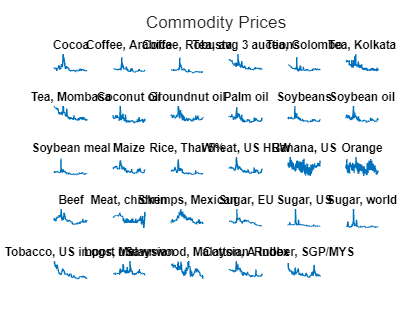

commodityNames = Prices.Properties.VariableNames;

figure
tiledlayout("flow", "TileSpacing", "tight")

for commodity = 1:width(Prices)
    nexttile
    plot(Prices.Date, Prices{:, commodity})
    title(commodityNames(commodity))   
    axis off
end

sgtitle("Commodity Prices")

## Compute the commodity price returns.

In subsequent analysis we will often require to work with the commodity price returns rather than the adjusted prices.

We convert the adjusted commodity prices $P_t$ to the return series $R_t$ as follows.


$$R_t = \frac{P_{t+1}}{P_t}-1, \quad t = 1, 2, 3, \dots$$


Returns = tick2ret(Prices);

## Visualize the commodity price returns.

Plot each return series over time.

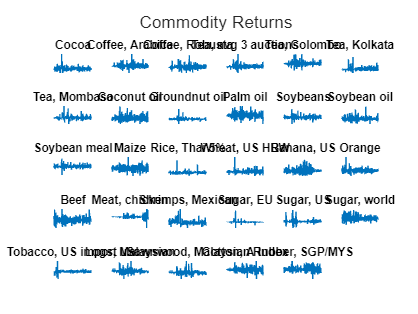

figure
tiledlayout("flow", "TileSpacing", "tight")

for commodity = 1:width(Returns)
    nexttile
    plot(Returns.Date, Returns{:, commodity})
    title(commodityNames(commodity))
    axis off
end

sgtitle("Commodity Returns")

## Save the commodity data for subsequent modelling and analysis.

save("Commodities.mat", "Prices", "Returns")